% 5 Laboratorinis darbas
% 2026-10-012
% Kiti duomenu tipai ir operaciju nuosekliai
% 22 variantas
%EIf-25 Jevgenij Malinkov
% 1)
C = cell(2,2);
help magic

 magic - Magic square
    This MATLAB function returns an n-by-n matrix constructed from the
    integers 1 through n2 with equal row and column sums.

    Syntax
      M = magic(n)

    Input Arguments
      n - Matrix order
        scalar integer

    Examples
      Third-Order Magic Square
      Magic Square Visualization

    See also ones, rand

    Introduced in MATLAB before R2006a
    Documentation for magic



C{1,1} = magic(3)

C = 2×2 cell array
    {3×3 double}    {0×0 double}
    {0×0 double}    {0×0 double}


C{1,2} = ones(2,4)

C = 2×2 cell array
    {3×3 double}    {2×4 double}
    {0×0 double}    {0×0 double}


C{2,1} = rand(4,1)

C = 2×2 cell array
    {3×3 double}    {2×4 double}
    {4×1 double}    {0×0 double}


C{2,2} = zeros(1,5)

C = 2×2 cell array
    {3×3 double}    {2×4 double }
    {4×1 double}    {[0 0 0 0 0]}


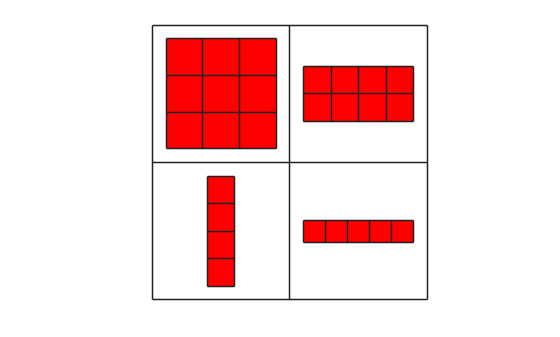


cellplot(C)   

disp(['Cell length: ', num2str(length(C))])

Cell length: 2


help iscell

 iscell - Determine if input is cell array
    This MATLAB function returns 1 (true) if A is a cell array.

    Syntax
      tf = iscell(A)

    Input Arguments
      A - Input array
        array

    Examples
      Determine If Arrays Are Cell Arrays

    See also cell, istable, iscellstr, isstruct, isnumeric, islogical,
      isobject, isa

    Introduced in M


if ~isempty(C) && iscell(C)
    ok = cellfun(@(x) isreal(x) && isa(x,'double') && ~isempty(x), C)
    if all(ok(:))
        cols = cellfun(@(x) x(:), C, 'UniformOutput', false)
        M = cell2mat(cols(:))
        disp('Combined matrix (column):')
        disp(M)
        disp(['Size: ', mat2str(size(M))])
    end
end

ok = 2×2 logical array
   1   1
   1   1


cols = 2×2 cell array
    {9×1 double}    {8×1 double}
    {4×1 double}    {5×1 double}


M =           8.00
          3.00
          4.00
          1.00
          5.00
          9.00
          6.00
          7.00
          2.00
          0.28
          0.05
          0.10
          0.82
          1.00
          1.00


Combined matrix (column):


          8.00
          3.00
          4.00
          1.00
          5.00
          9.00
          6.00
          7.00
          2.00
          0.28
          0.05
          0.10
          0.82
          1.00
          1.00
          1.00
          1.00
          1.00
          1.00
          1.00
          1.00
             0
             0
             0
             0
             0



Size: [26 1]


clc; clear;

rates = [0.10 0.15 0.20]

rates =           0.10          0.15          0.20


amounts = 10000:1000:20000

amounts =       10000.00      11000.00      12000.00      13000.00      14000.00      15000.00      16000.00      17000.00      18000.00      19000.00      20000.00


term = 12

term =          12.00



format bank
table = zeros(length(amounts), 4)

table =              0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0



for i = 1:length(amounts)
    table(i,1) = amounts(i)
    for j = 1:length(rates)
        r = rates(j)/12;                                     
        table(i,j+1) = amounts(i) * r / (1 - (1+r)^(-term));  
    end
end

table =       10000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00       1230.82       1263.62       1296.88
      15000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00       1230.82       1263.62       1296.88
      15000.00       1318.74       1353.87       1389.52
      16000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00       1230.82       1263.62       1296.88
      15000.00       1318.74       1353.87       1389.52
      16000.00       1406.65       1444.13       1482.15
      17000.00             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00       1230.82       1263.62       1296.88
      15000.00       1318.74       1353.87       1389.52
      16000.00       1406.65       1444.13       1482.15
      17000.00       1494.57       1534.39       1574.79
      18000.00             0             0             0
             0             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00       1230.82       1263.62       1296.88
      15000.00       1318.74       1353.87       1389.52
      16000.00       1406.65       1444.13       1482.15
      17000.00       1494.57       1534.39       1574.79
      18000.00       1582.49       1624.65       1667.42
      19000.00             0             0             0
             0             0             0             0


table =       10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00       1230.82       1263.62       1296.88
      15000.00       1318.74       1353.87       1389.52
      16000.00       1406.65       1444.13       1482.15
      17000.00       1494.57       1534.39       1574.79
      18000.00       1582.49       1624.65       1667.42
      19000.00       1670.40       1714.91       1760.06
      20000.00             0             0             0



disp('  Loan (EUR)    Bank 1      Bank 2      Bank 3')

  Loan (EUR)    Bank 1      Bank 2      Bank 3


disp(table)

      10000.00        879.16        902.58        926.35
      11000.00        967.07        992.84       1018.98
      12000.00       1054.99       1083.10       1111.61
      13000.00       1142.91       1173.36       1204.25
      14000.00       1230.82       1263.62       1296.88
      15000.00       1318.74       1353.87       1389.52
      16000.00       1406.65       1444.13       1482.15
      17000.00       1494.57       1534.39       1574.79
      18000.00       1582.49       1624.65       1667.42
      19000.00       1670.40       1714.91       1760.06
      20000.00       1758.32       1805.17       1852.69



clear 
clear all
%Papildoma uzduotis
%21 variantas
s = input('Enter a sentence: ', 's');

result = '';
removed = 0;

for i = 1:length(s)
    if s(i) == ' '
        if i > 1 && s(i-1) == ' '
            removed = removed + 1;
        else
            result = [result s(i)];
        end
    else
        result = [result s(i)];
    end
end

disp(['Result: ', result])

Result: labas vakaras


disp(['Removed spaces: ', num2str(removed)])

Removed spaces: 5
